# Escuela Politécnica Nacional

# Chunk-based Malware Classifiers for Communication Networks

# (Aprendizaje no Supervisado)

# Proyecto de Fin de Módulo Redes Neuronales

**Autor:** David Cevallos

**Fecha:** 2023-08-15

% Aprendizaje no Supervisado
% Identificación y clasificación de Malware 
tic;
clc;
clear;
close all;
warning("off","all");

% Limpieza de datos
T = readtable("Obfuscated-MalMem2022.csv", "ReadVariableNames",true);
X = table2array(T(:,2:end-1));
[N,~] = size(X);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 16

k = 16

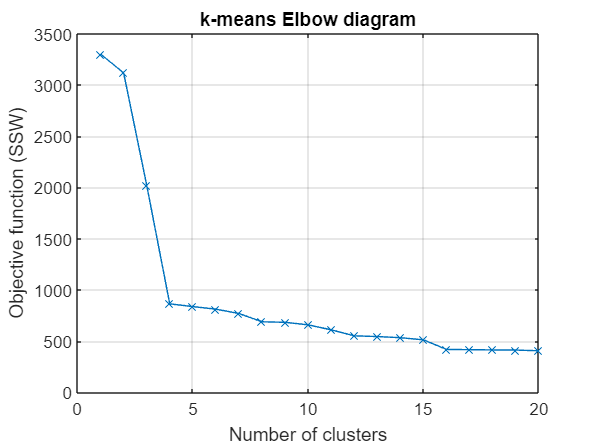

rng(0);

% Diagrama de codo
for i =1:n
    rng(0);
    [idx, C, SumD] = kmeans(X,i);
    SSWkm(i) = SSW(X,idx);
    Kkm(i)=i;
end

figure;
plot(Kkm, SSWkm,"-x");
grid on;
xlabel("Number of clusters");
ylabel("Objective function (SSW)");
title("k-means Elbow diagram");


% Clustering
rng(0);
idx = kmeans(X,k);

% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW_km,SSB_km,WB_km,SIL_km]=MetricasNoSupervisado(X,idx)

SSW_km = 418.5362

SSB_km = 3.2766e+03

WB_km = 2.0437

SIL_km = 0.6815


% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 16

k = 16

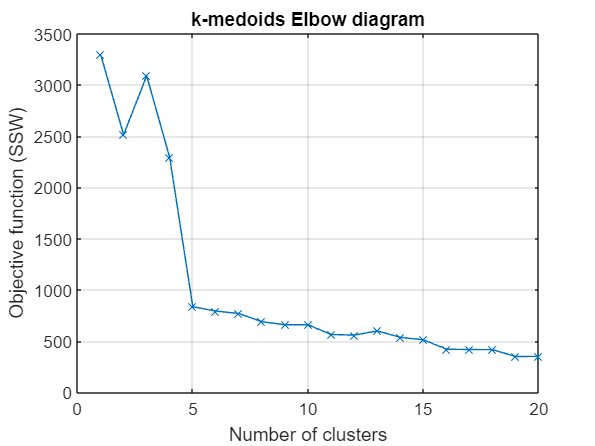

rng(0);

% Diagrama de codo
for i =1:n
    rng(0);
    [idx, C, SumD] = kmedoids(X,i);
    SSWkmd(i) = SSW(X,idx);
    Kkmd(i)=i;
end

figure;
plot(Kkmd, SSWkmd,"-x");
grid on;
xlabel("Number of clusters");
ylabel("Objective function (SSW)");
title("k-medoids Elbow diagram");


% Clustering
rng(0);
idx = kmedoids(X,k);

% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW_kmd,SSB_kmd,WB_kmd,SIL_kmd]=MetricasNoSupervisado(X,idx)

SSW_kmd = 420.7788

SSB_kmd = 3.2758e+03

WB_kmd = 2.0552

SIL_kmd = 0.6631


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


rng(0);
cpart = sort(randsample(N,30000));
Xsample = X(cpart,:);

n = 20

n = 20

k = 16

k = 16

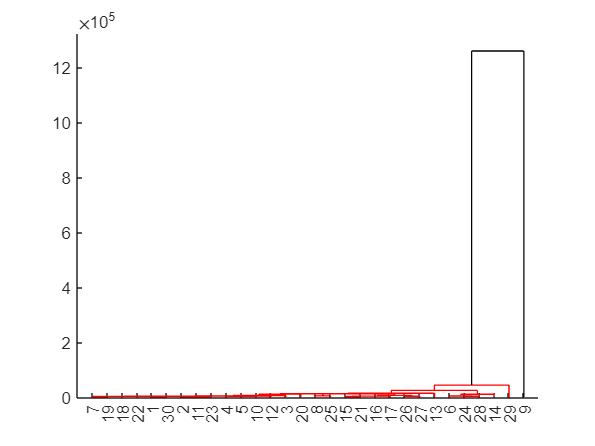

rng(0);

% Dendrograma
tree = linkage(Xsample,"single","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

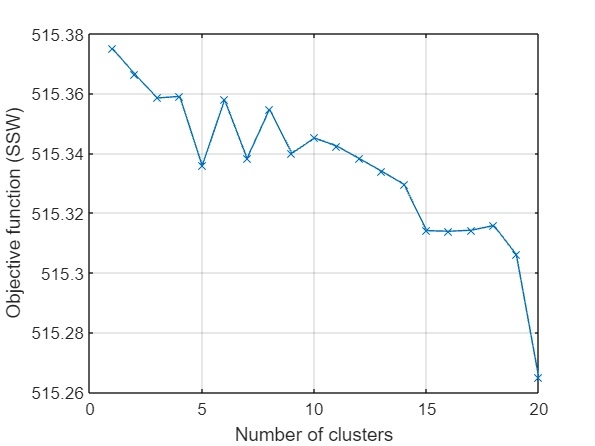


% Diagrama de codo
for i =1:n
    rng(0);
    idx = cluster(tree,"maxclust",i);
    SSWhc(i) = SSW(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Number of clusters");
ylabel("Objective function (SSW)");


% Clusterización
rng(0);
idx = cluster(tree,"maxclust",k);

% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

SSW_hc = SSW(X,idx)

SSW_hc = 515.3139

[SSW_hc,SSB_hc,WB_hc] = SSW(X,idx)

SSW_hc = 515.3139

SSB_hc = 1.0978e+03

WB_hc = 7.5107

[~,~,~,SIL_hc]= MetricasNoSupervisado(Xsample,idx)

SIL_hc = 0.8410


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

c = 16

c = 16


% Diagrama de codo
for i =1:n
    rng(0);
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    SSWfcm(i) = SSW(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 1261.477675
Iteration count = 2, obj. fcn = 51.199220
Iteration count = 3, obj. fcn = 6.704719
Iteration count = 4, obj. fcn = 3.284141
Iteration count = 5, obj. fcn = 2.414191
Iteration count = 6, obj. fcn = 1.462477
Iteration count = 7, obj. fcn = 0.361144
Iteration count = 8, obj. fcn = 0.113425
Iteration count = 9, obj. fcn = 0.000075
Iteration count = 10, obj. fcn = 0.000000
Iteration count = 11, obj. fcn = 0.000000
Minimum improvement reached.
Iteration count = 1, obj. fcn = 2449254435170.374023
Iteration count = 2, obj. fcn = 2135330777391.924561
Iteration count = 3, obj. fcn = 2135258000416.152100
Iteration count = 4, obj. fcn = 2134616946893.897705
Iteration count = 5, obj. fcn = 2129209524909.062012
Iteration count = 6, obj. fcn = 2096325494533.142578
Iteration count = 7, obj. fcn = 2045065179440.894531
Iteration count = 8, obj. fcn = 2037975059205.372070
Iteration count = 9, obj. fcn = 2037856663210.368652
Iteration count = 10, obj. fcn = 2037

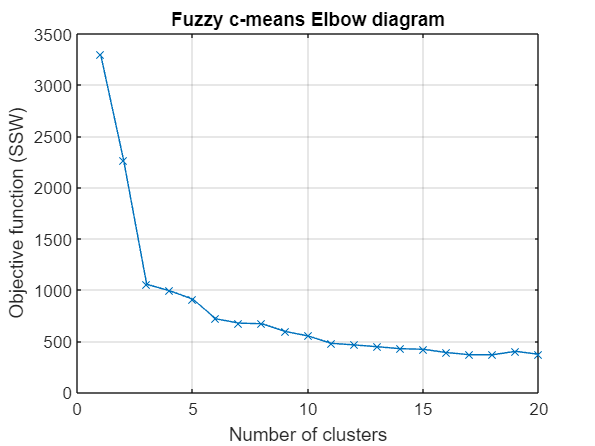


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Number of clusters");
ylabel("Objective function (SSW)");
title("Fuzzy c-means Elbow diagram");


% Clusterización
rng(0);
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 371722781221.639771
Iteration count = 2, obj. fcn = 266909261913.087769
Iteration count = 3, obj. fcn = 266844678341.983582
Iteration count = 4, obj. fcn = 266300921966.480469
Iteration count = 5, obj. fcn = 262767975554.680115
Iteration count = 6, obj. fcn = 254074124683.184784
Iteration count = 7, obj. fcn = 242670951664.866821
Iteration count = 8, obj. fcn = 210357502037.974487
Iteration count = 9, obj. fcn = 195715983711.704163
Iteration count = 10, obj. fcn = 191087778662.167358
Iteration count = 11, obj. fcn = 187770060700.393982
Iteration count = 12, obj. fcn = 184193545271.754761
Iteration count = 13, obj. fcn = 180998964012.694000
Iteration count = 14, obj. fcn = 178310114871.056183
Iteration count = 15, obj. fcn = 175164535180.252747
Iteration count = 16, obj. fcn = 170515272117.955505
Iteration count = 17, obj. fcn = 163017743375.840088
Iteration count = 18, obj. fcn = 156702958583.084045
Iteration count = 19, obj. fcn = 151500343191.424622
It

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW_fcm,SSB_fcm,WB_fcm,SIL_fcm]=MetricasNoSupervisado(X,idx)

SSW_fcm = 387.7675

SSB_fcm = 3.2732e+03

WB_fcm = 1.8955

SIL_fcm = 0.5233


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------


rng(0);
cpart = sort(randsample(N,20000));
Xsample = X(cpart,:);

% Clustering
rng(0);
min_n = 3

min_n = 3

ep = clusterDBSCAN.estimateEpsilon(Xsample,min_n,min_n)

ep = 2.0491e+03

idx = dbscan(Xsample,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 15

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 31 anomalías


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW_dbs,SSB_dbs,WB_dbs] = SSW(X,idx)

SSW_dbs = 297.8611

SSB_dbs = 770.2884

WB_dbs = 6.1870

[~,~,~,SIL_dbs]= MetricasNoSupervisado(Xsample,idx)

SIL_dbs = 0.8945

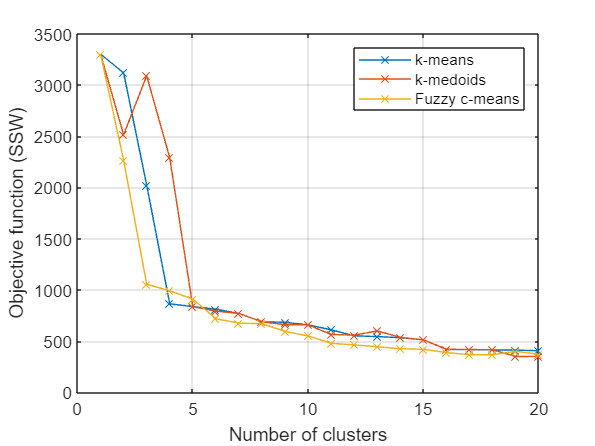


% Gráfica general
figure;
plot(Kkm,SSWkm,"-x");
hold on;
plot(Kkmd,SSWkmd,"-x");
hold on;
plot(Kfcm,SSWfcm,"-x");
grid on;
legend("k-means", "k-medoids", "Fuzzy c-means");
xlabel("Number of clusters");
ylabel("Objective function (SSW)");


toc

Elapsed time is 265.764672 seconds.
